# Global sensitivity and uncertainty analysis toolbox (GSUA)

## 1. Introduction

The GSUA Toolbox [1] implements uncertainty and sensitivity analysis (global and OAT) of dynamical (with differential equations) and static (functions) models. The Saltelli and brute-force global sensitivity methods [2] are implemented. The one-at-a-time (OAT) local method is applicable correctly only if the interaction between factors is small ($\sum S_1 >0.65$), so first-order sensitivity indices should be carefully reviewed. The toolbox needs the following two files: 1) This Live Script file. 2) A mathematical model in a slx-file (Simulink) or m-file (ode45), as shown in the examples given in the toolbox. See **help** at the end of this document.

## 2. Method

### **Data**

S = [];
S.description = 'goodwinModel'; 
S.factor_names = 'nu alpha beta delta phi0 phi1 omega0 lambda0';
S.x_nom = '[3 0.025 0.02 0.01 0.04/(1-0.04^2) 0.04^3/(1-0.04^2) 0.8 0.9]';
S.x_uncer = '[2 10 10 10 10 10 1 1]'; 
S.x_dist = 'L';
S.model = 'goodwin_ode';

### **Method characteristics**

S.sens_method = "OAT";
S.N = 2000;
S.rngN = 0;
S.scalar_characteristic = 'sum((y-ynom).^2)';
S.Save_to_file = "";
S = gsua_input(S);

### **Nominal values and uncertainties**

disp(S.x_table)

               Nominal values    Uncertainty (%)    Distribution
               ______________    _______________    ____________

    nu           3                     2                 L      
    alpha        0.025                 10                L      
    beta         0.02                  10                L      
    delta        0.01                  10                L      
    phi0         0.040064              10                L      
    phi1         6.4103e-05            10                L      
    omega0       0.8                   1                 L      
    lambda0      0.9                   1                 L      



## **3. Calculations**

Elapsed percentage, remaining computing time, estimated stop time.

 
S = gsua_sample(S); % Monte Carlo sampling
S = gsua_methods(S); % Uncertainty ans sensitivity analysis

Elapsed percentage: 00.1%  Remaining computing time: 00h:01m:11s  Estimated stop time: 17:35:27
Elapsed percentage: 03.8%  Remaining computing time: 00h:01m:10s  Estimated stop time: 17:35:29
Elapsed percentage: 08.8%  Remaining computing time: 00h:01m:07s  Estimated stop time: 17:35:29
Elapsed percentage: 12.6%  Remaining computing time: 00h:01m:04s  Estimated stop time: 17:35:29
Elapsed percentage: 16.2%  Remaining computing time: 00h:01m:01s  Estimated stop time: 17:35:28
Elapsed percentage: 21.2%  Remaining computing time: 00h:00m:57s  Estimated stop time: 17:35:28
Elapsed percentage: 25.1%  Remaining computing time: 00h:00m:54s  Estimated stop time: 17:35:28
Elapsed percentage: 28.7%  Remaining computing time: 00h:00m:52s  Estimated stop time: 17:35:28
Elapsed percentage: 33.8%  Remaining computing time: 00h:00m:48s  Estimated stop time: 17:35:28
Elapsed percentage: 37.6%  Remaining computing time: 00h:00m:45s  Estimated stop time: 17:35:28
Elapsed percentage: 41.2%  Remaining com

if ~strcmp(S.Save_to_file,'')
    save(S.Save_to_file,'S')
end

## %4. Resume of method and calculations

% 
%S = gsua_sim_resume(S);
%disp(S.sim_resume)

## 5. Results

% Figure properties
S.uncer_title = 'Fig. 1. Uncertainty plot';
S.uncer_max = max(S.x_uncer);
S.S1_title = 'Fig. 2. S1 - Vectorial first-order sensitivity indices';
S.S1_plot_type = 'barh';
S.ST_title = 'Fig. 3. ST - Vectorial normalized total sensitivity indices';
S.ST_plot_type = 'barh';
S.S1s_title = ['Fig. 4. S1s - Scalar first-order sensitivity indices, y = ' char(S.scalar_characteristic) ', sum = ' num2str(sum(S.S1s))];
S.S1s_plot_type = 'barh';
S.STs_title = ['Fig. 5. STs - Scalar total sensitivity indices, y = ' char(S.scalar_characteristic)];
S.STs_plot_type = 'barh';
S.scatter_output_title = 'Fig. 6. Scatter plots of scalar output';
S.scatter_factor_title = 'Fig. 7. Scatter plot of factor samples';
S.title_fontsize = 10;
S.title_color = 'k';
S.title_FontWeight = 'bold';

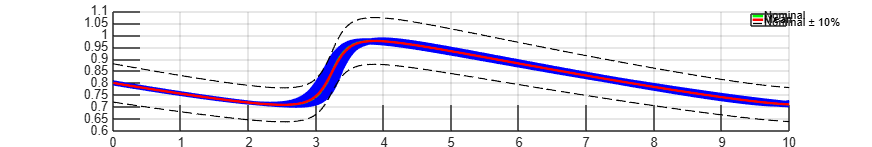

 
figure('Units','normalized','Position',[0 0 1 0.3]) 
gsua_plot_uncertainty(S)

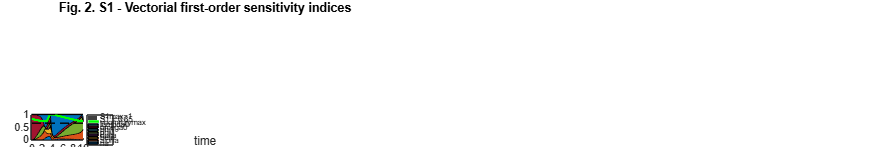

Try to use a longer N: the first-order indices must be positive and their sum should be less than 1.


 
figure('Units','normalized','Position',[0 0 1 0.3])
subplot(1,2,1)
gsua_plot_sensitivity('S1',S)

legend('show', 'Location', 'northeastoutside');  % Places the legend outside the plot area

if ~isempty(S.ST)
    subplot(1,2,2)
    gsua_plot_sensitivity('ST',S)
end

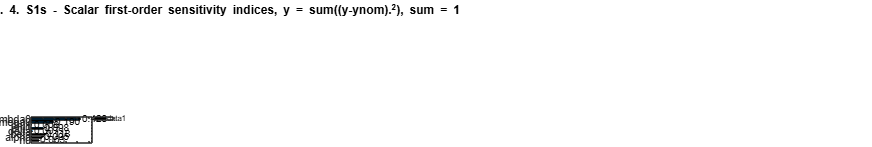

 
figure('Units','normalized','Position',[0 0 1 0.3])
subplot(1,2,1)
gsua_plot_sensitivity('S1s',S)

if ~isempty(S.STs)
    subplot(1,2,2)
    gsua_plot_sensitivity('STs',S)
end

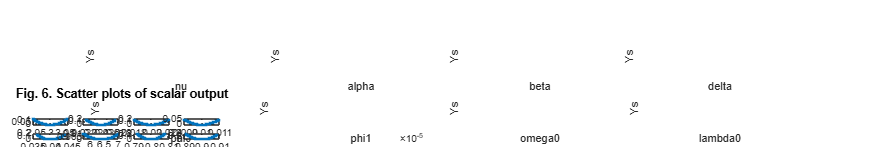

 
figure('Units','normalized','Position',[0 0 1 0.3]) 
gsua_plot_scatter_output(S)

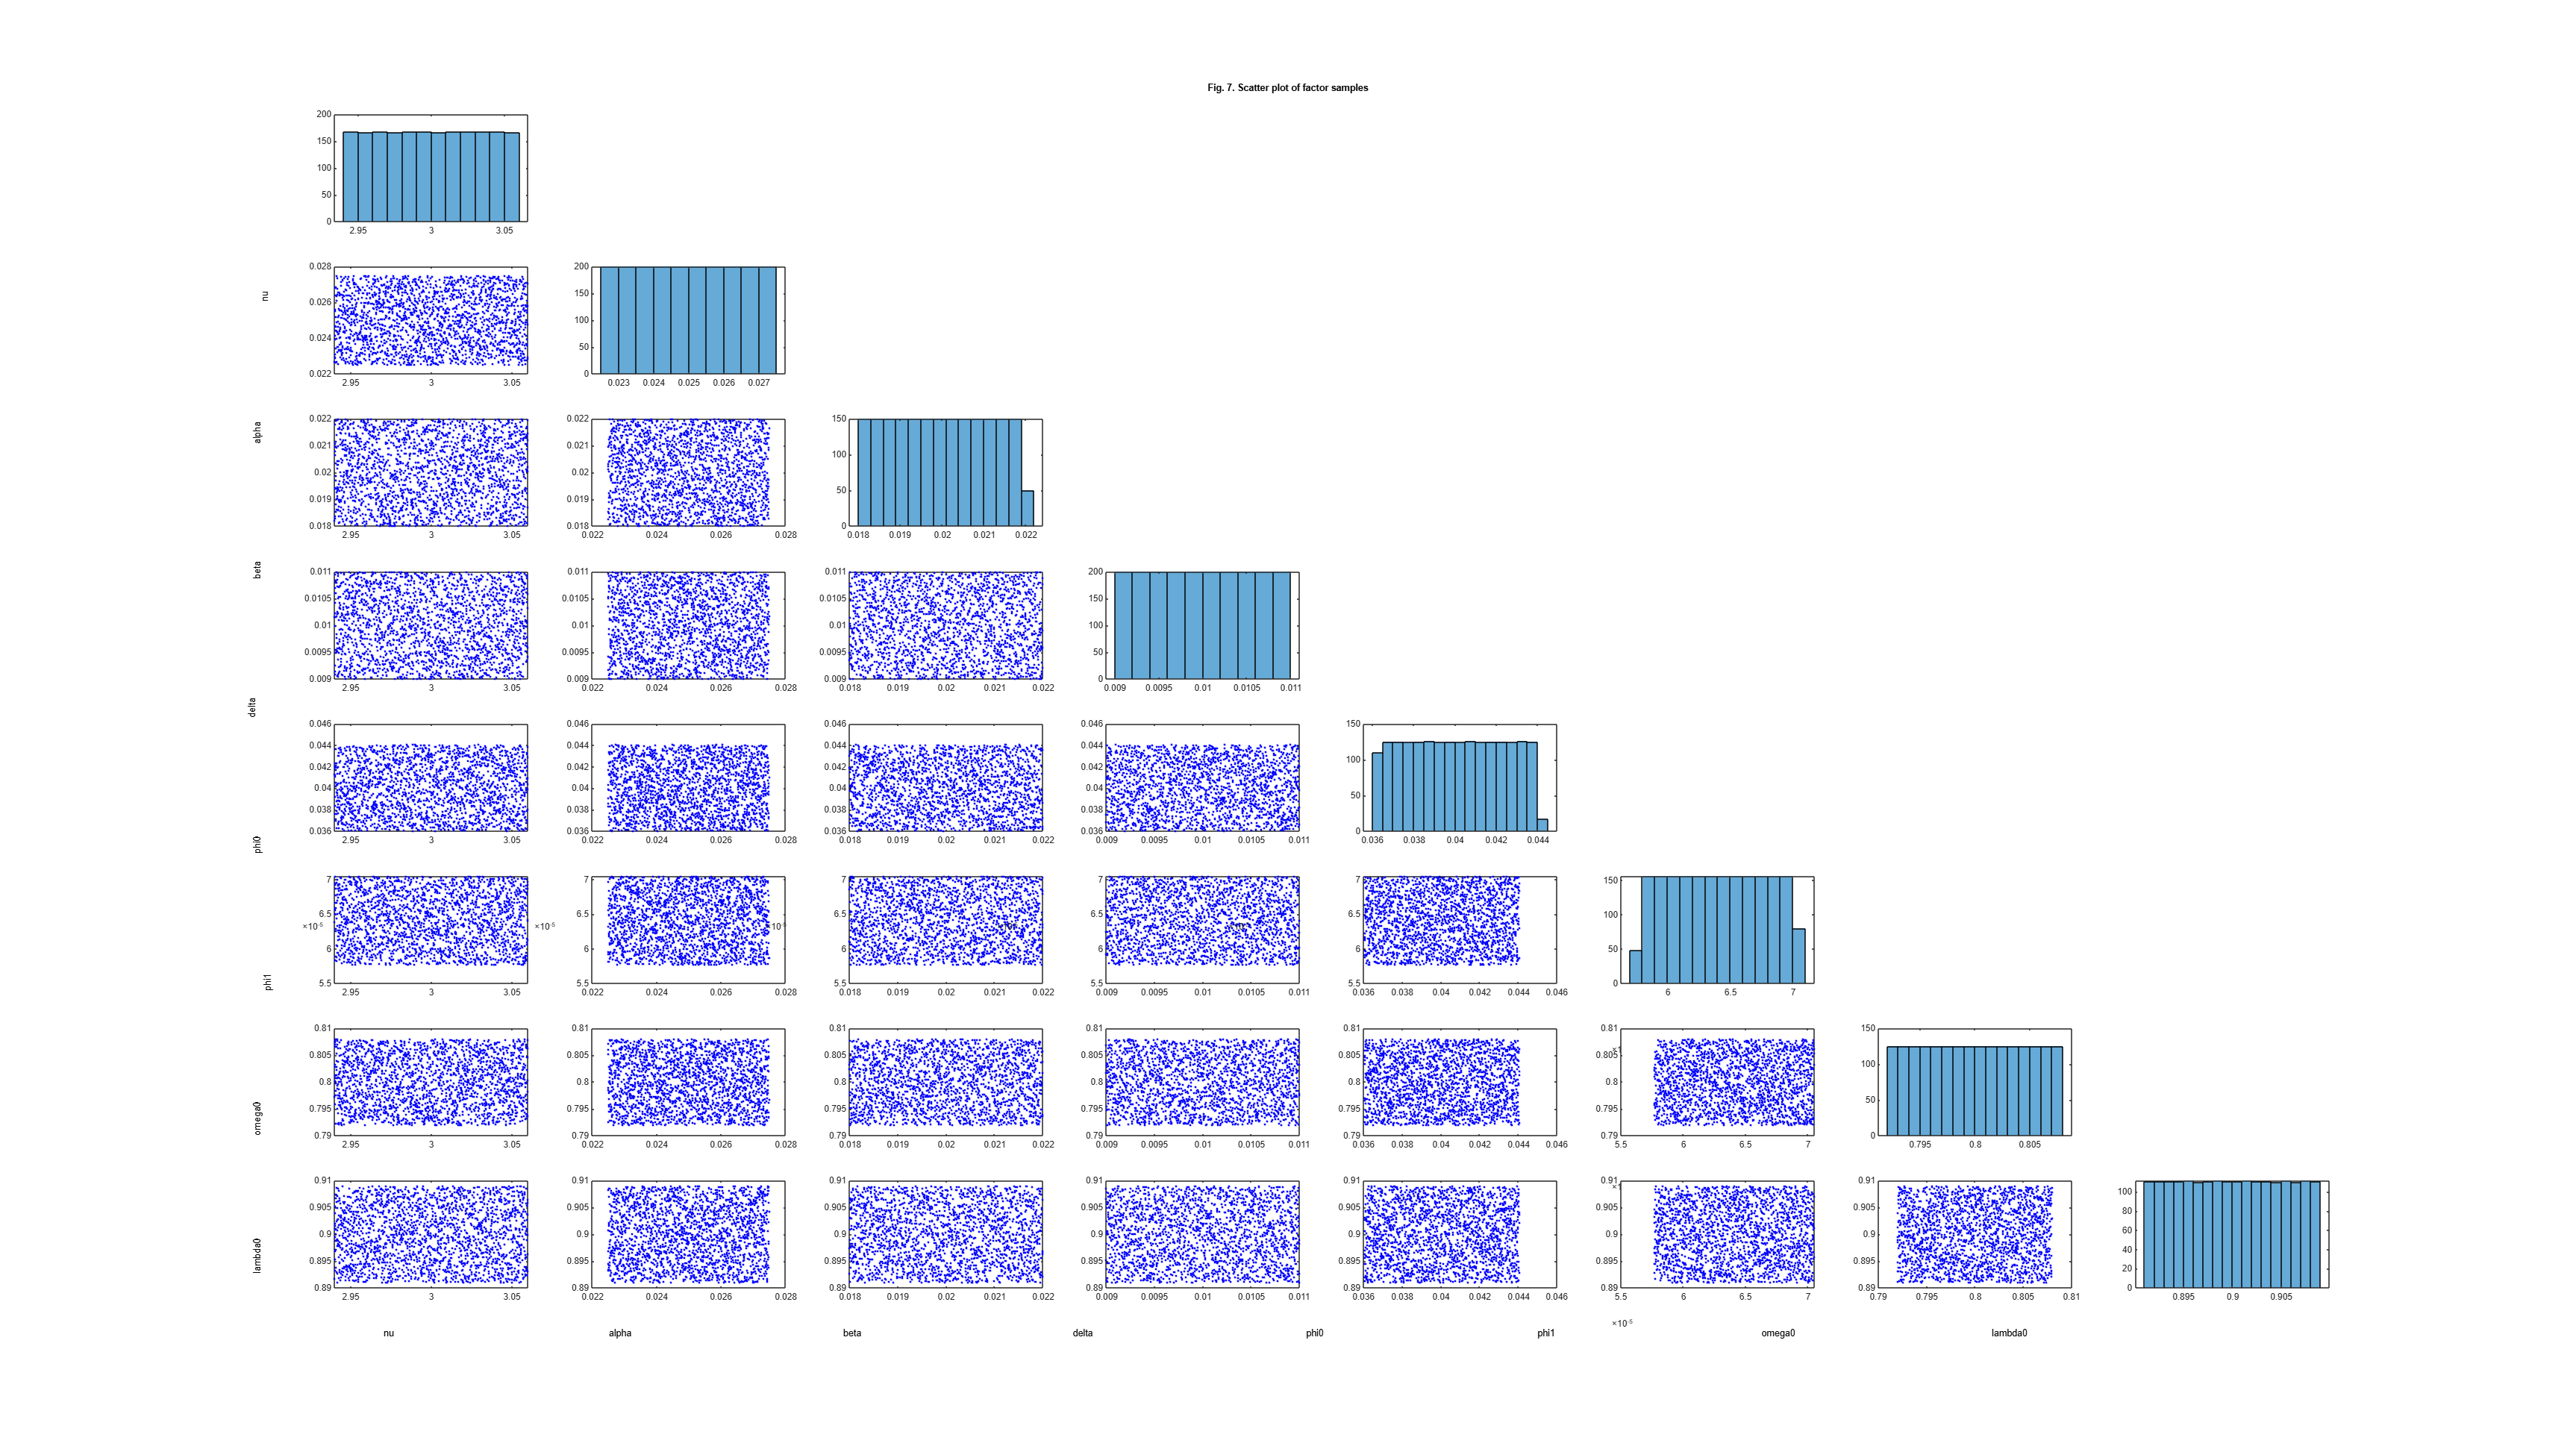

 
figure('Units','normalized','Position',[0 0 1 1]) 
gsua_plot_scatter_factors(S)

## **6. Help**

- To generate only the plots from a previous experiment, load a MAT file with the experiment data and run only the commands in section 5 (results).

- To modify x-label, y-label and grid of a figure, you can select the figure and change the respective characteristic from "Figure" tab of Live Script program.

- To modify title (text, font size, color, etc.) and plot type of a figure, you can change them in the code of section 5.

- (1) Project description.

- (2) Factor names. (1xNp) matrix. Example (without quotes, brackets or commas): k f m x(0)

- (3) Factor nominal values. Example: [1.5 4.3 25 0.15]. If a nominal value is equal to zero (x' = ax, a = 0 ± da), it is necessary to do a transformation: x' = (1 - a)x, a = 1 ± da.  

- (4) Factor uncertainties in percentage. Examples: (1) [2.4 0.8 13 20]. (2) 20 (if the same value applies for every factor)

- (5) Factor sampling distribution function. L (LatinHypercube), U (Uniform), N (Normal). Examples: (1) L N L U. (2) L (if the same distibution applies for every factor).

- (6) Simulation model file. Options: 1) In the case of a *Simulink Model*, the file has some simple special structure: use a "To Workspace" connected to the output with sample time**,** variable name "yout" and "Structure with time" format. The parameters of models are defined with variable x. The Simulink model uses a lot of more computational time, but is the prefered method for hybrid dynamical systems (systems with continuous and discrete subsystems) and control systems. 2) In the case of a m-file (the preferred format), specify a model using the ode45 function (see examples in the toolbox). 3) The model must give bounded outputs (if the simulation stops before the final time, the toolbox does not work properly). 

- (7) Variance-based sensitivity method. Options: Saltelli, Bruteforce, OAT.

- (8) Number of samples. Try to use a longer N if the first-order indices are negative or their sum is more than 1.

- (9) Seed of random numbers. Options: 0 (for random seed) or other number (to obtain the same results).

- (10) Scalar output. The function must always include the variable *y*. Examples (without quotes): 'sum((y-ynom).^2)', 'max(y)', 'stepinfo(y,t).PeakTime', 'stepinfo(y,t).RiseTime', 'stepinfo(y,t).Overshoot', 'stepinfo(y,t).SettlingTime', 'mean(y(end-10:end))', 'trapz(y)', 'max(y) - y(end)'

- (11) Save file name to current folder: mat-file name. Leave the field empty if you do not want to store the results.

- Fig. 1. Uncertainty plot. Cases: 1) Dynamical case: time response for every family of factors (the nominal or experimental time output is highlighted); 2) Static case (function): histogram plot which shows how the output varies with changes on factors.

- Fig. 2. Vectorial first-order sensitivity indices plot (S1). Cases: 1) Dynamical case: vectorial first-order sensitivity indices which depend on time; 2) Static case (function): scalar first-order sensitivity indices for the scalar function value. The first-order indices must be positive and their sum should be less than one, so if these conditions are not met, it is necessary to increase sample size N.

- Fig. 3. Vectorial total sensitivity indices plot (ST). Cases: 1) Dynamical case: normalized vectorial total sensitivity indices which depend on time; 2) Static case (function): normalized scalar total sensitivity indices for the scalar function value. In the OAT sensitivity method this plot does not apply.

- Fig. 4. Scalar first-order sensitivity indices (S1s). A bar or pie chart can be used. Cases: 1) Dynamical case: scalar first-order sensitivity indices for the scalar characteristic of time response using pie or bar plots; 2) Static case (function): scalar first-order sensitivity indices for the squared error. The first-order indices must be positive and their sum should be less than one, so if these conditions are not met, it is necessary to increase sample size N.

- Fig. 5. Scalar total sensitivity indices (STs).  A bar or pie chart can be used. Cases: 1) Dynamical case: scalar total sensitivity indices for the scalar characteristic of time response using pie or bar plots; 2) Static case (function): normalized scalar total sensitivity indices for the squared error. In the OAT sensitivity method this plot does not apply.

- Fig. 6. Scatter plots of output. Ys is a function of factors. Look for correlations and relative values.

- Fig. 7. Scatter plots of factors. These plots depend on every factor distribution function.

## 7. References

- Velez, C. M. (2024). Global sensitivity and uncertainty analysis (GSUA) (https://www.mathworks.com/matlabcentral/fileexchange/47758-global-sensitivity-and-uncertainty-analysis-gsua), MATLAB Central File Exchange.

- Saltelli, A., et al (2010). Variance based sensitivity analysis of model output. Design and estimator for the total sensitivity index. Computer Physics Communications, 181(2), 259-270.